#  Kulite Calibrations

% Load in raw voltage output data before executing 

% Convert Data tables into arrays
% 
% Kcal1 = table2array(Kcal1);
% Kcal2 = table2array(Kcal2);
% Kcal3 = table2array(Kcal3);
% Kcal4 = table2array(Kcal4);
% Kcal5 = table2array(Kcal5);
% Kcal6 = table2array(Kcal6);
% Kcal7 = table2array(Kcal7);
% 
% Dcal1 = table2array(Dcal1);
% Dcal2 = table2array(Dcal2);
% Dcal3 = table2array(Dcal3);
% Dcal4 = table2array(Dcal4);
% Dcal5 = table2array(Dcal5);
% 
% Run1_DT = table2array(Run1_DT);
% Run2_DT = table2array(Run2_DT);
% Run3_DT = table2array(Run3_DT);
% Run4_DT = table2array(Run4_DT);
% Run5_DT = table2array(Run5_DT);
% Run6_DT = table2array(Run6_DT);
% Run7_DT = table2array(Run7_DT);
% Run8_DT = table2array(Run8_DT);
% Run9_DT = table2array(Run9_DT);
% Run10_DT = table2array(Run10_DT);
% Run11_DT = table2array(Run11_DT);
% Run12_DT = table2array(Run12_DT);

Run1_K = table2array(Run1_K);
Run2_K = table2array(Run2_K);
Run3_K = table2array(Run3_K);
Run4_K = table2array(Run4_K);
Run5_K = table2array(Run5_K);
% Run6_K = table2array(Run6_K);
% Run7_K = table2array(Run7_K);
% Run8_K = table2array(Run8_K);
% Run9_K = table2array(Run9_K);
% Run10_K = table2array(Run10_K);
% Run11_K = table2array(Run11_K);
% Run12_K = table2array(Run12_K);



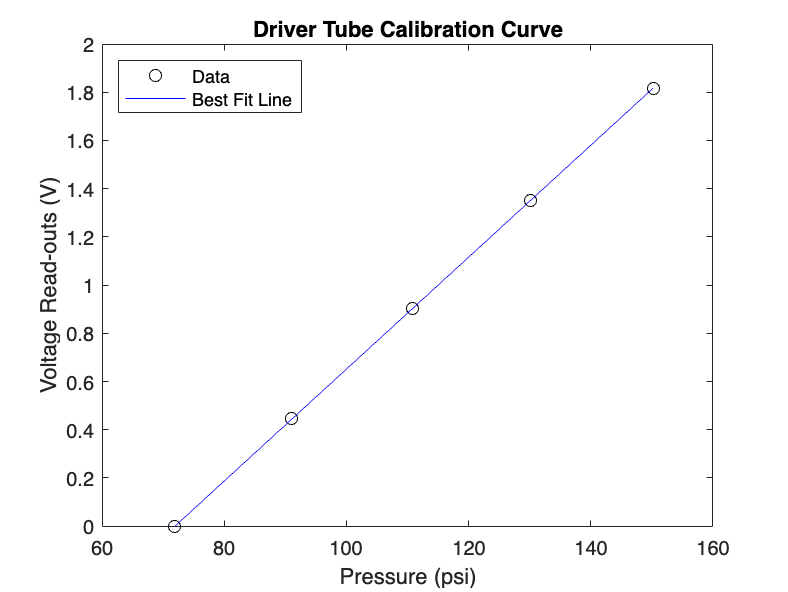

% Plot Driver tube and Kulite calibration curves

% Dcal data
Dcal_points = [sum(Dcal1)./(height(Dcal1)), sum(Dcal2)./(height(Dcal2)), sum(Dcal3)./(height(Dcal3)), sum(Dcal4)./(height(Dcal4)), sum(Dcal5)./(height(Dcal5))];
Dcal_pressures = [71.9 91.0 110.8 130.1 150.2];

% Calibration Curve
Dcal_fit_coeffs = polyfit(Dcal_pressures, Dcal_points, 1);
Dcal_fit = polyval(Dcal_fit_coeffs, Dcal_pressures);

% Plot Dcal data and best-fit line
figure;
plot(Dcal_pressures, Dcal_points, 'ko', 'DisplayName', 'Data');
hold on
plot(Dcal_pressures, Dcal_fit, 'b-', 'DisplayName', 'Best Fit Line');
hold off
legend('Location', 'northwest')
xlabel('Pressure (psi)');
ylabel('Voltage Read-outs (V)');
title('Driver Tube Calibration Curve');

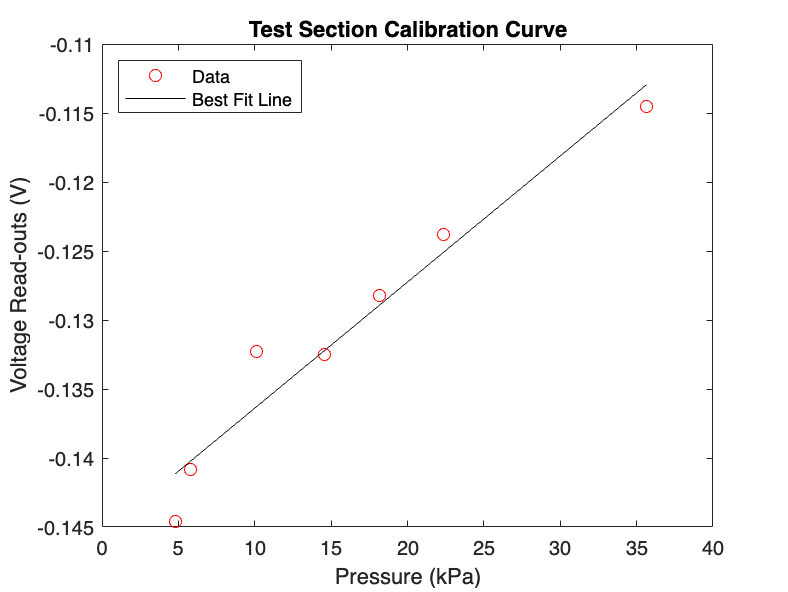


% For Kcal data
Kcal_points = [sum(Kcal1)./(height(Kcal1)), sum(Kcal2)./(height(Kcal2)), sum(Kcal3)./(height(Kcal3)), sum(Kcal4)./(height(Kcal4)), sum(Kcal5)./(height(Kcal5)), sum(Kcal6)./(height(Kcal6)), sum(Kcal7)./(height(Kcal7))];
Kcal_pressures = [35.65 22.38 18.18 14.55 10.09 5.80 4.80];

% Find best-fit line for Kcal data
Kcal_fit_coeffs = polyfit(Kcal_pressures, Kcal_points, 1);
Kcal_fit = polyval(Kcal_fit_coeffs, Kcal_pressures);

% Plot Kcal data and best-fit line
figure;
plot(Kcal_pressures, Kcal_points, 'ro', 'DisplayName', 'Data');
hold on
plot(Kcal_pressures, Kcal_fit, 'k-', 'DisplayName', 'Best Fit Line');
hold off
legend('Location', 'northwest')
xlabel('Pressure (kPa)');
ylabel('Voltage Read-outs (V)');
title('Test Section Calibration Curve');

% Plots of Test Run Driver Tube Pressures
figure;

plot(Run1_DT, width(Run1_DT), 'DisplayName', 'Test 1');
hold on;
plot(Run2_DT, width(Run2_DT), 'DisplayName', 'Test 2');
plot(Run3_DT, width(Run3_DT), 'DisplayName', 'Test 3');
plot(Run4_DT, width(Run4_DT), 'DisplayName', 'Test 4');
plot(Run5_DT, width(Run5_DT), 'DisplayName', 'Test 5');

% Adding labels and legend
title('Voltage Outputs of Runs 1 - 5');
xlabel('Index');
ylabel('Voltage Output (V)');
legend('show');

hold off;


% Plots of Test Run Kulite Pressures

figure;

plot(Run1_K, width(Run1_K), 'DisplayName', 'Test 1');
hold on;
plot(Run2_K, width(Run2_K), 'DisplayName', 'Test 2');
plot(Run3_K, width(Run3_K), 'DisplayName', 'Test 3');
plot(Run4_K, width(Run4_K), 'DisplayName', 'Test 4');
plot(Run5_K, width(Run5_K), 'DisplayName', 'Test 5');

% Adding labels and legend
title('Voltage Outputs of Runs 1 - 5');
xlabel('Index');
ylabel('Voltage Output (V)');
legend('show');

hold off;